mian=[0.01 0.5 3 -10 10];
licz=[1 1]

licz =      1     1


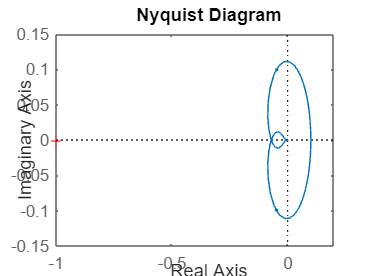

G=tf(licz,mian);
[re,im,wout]=nyquist(G);

nyquist(G)

%układ stabilny
P=2; %2 bieguny dodatnie
r1=pole(1)

Incorrect number or types of inputs or outputs for function pole.

r2=pole(60)

przedzial1=linspace(-1/r1,0,100)%krotność 1
przedzial2=linspace(0,-1/r2,100)%krotność 2

liczH=[1];
mianH=[1 0];
H=tf(liczH,mianH);
G1=series(G,H)

G1 =
 
                    s + 1
  ------------------------------------------
  0.01 s^5 + 0.5 s^4 + 3 s^3 - 10 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


Gz=G/1+G

Gz =
 
                        0.02 s^5 + 1.02 s^4 + 7 s^3 - 14 s^2 + 20
  -------------------------------------------------------------------------------------
  0.0001 s^8 + 0.01 s^7 + 0.31 s^6 + 2.8 s^5 - 0.8 s^4 - 50 s^3 + 160 s^2 - 200 s + 100
 
Continuous-time transfer function.
Model Properties


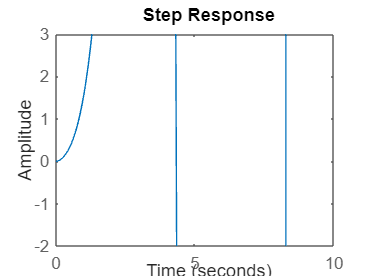

step(Gz)
xlim([0 10])
ylim([-2 3])

poleZ=pole(Gz)

Unable to use a value of type tf as an index.

pole appears to be both a function and a variable. If this is unintentional, use 'clear pole' to remove the variable 'pole' from the workspace.

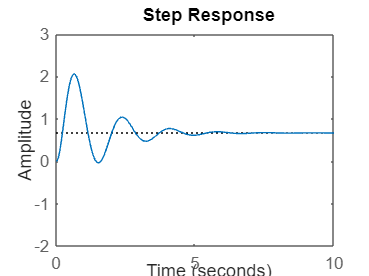

%wzmocnienie 20
k1=20;
mian=[0.01 0.5 3 -10 10];
licz=[1 1];
G=tf(licz,mian);
Gcl1 = minreal(k1*G/(1+k1*G));
%G=G/1+G;
step(Gcl1)
xlim([0 10])
ylim([-2 3])
saveas(gcf,'k_20.png')

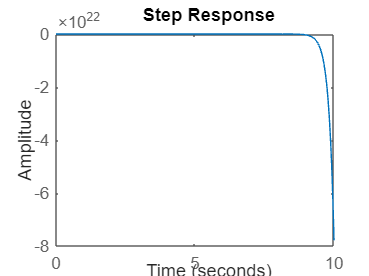

%wzmocnienie -20
k1=-20;
mian=[0.01 0.5 3 -10 10];
licz=[1 1];
G=tf(licz,mian);
Gcl1 = minreal(k1*G/(1+k1*G));
%G=G/1+G;
step(Gcl1)
xlim([0 10])
%ylim([-2 3])
saveas(gcf,'k_-20.png')

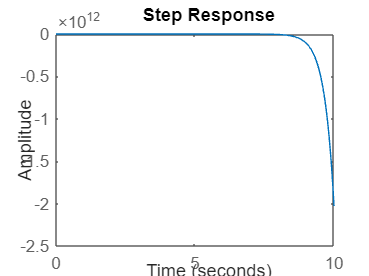

%wzmocnienie -5
k1=-5;
mian=[0.01 0.5 3 -10 10];
licz=[1 1];
G=tf(licz,mian);
Gcl1 = minreal(k1*G/(1+k1*G));
%G=G/1+G;
step(Gcl1)
xlim([0 10])
%ylim([-2 3])
saveas(gcf,'k_-5.png')

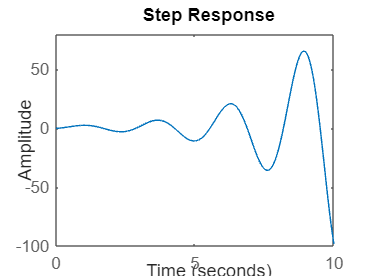

%wzmocnienie 5
k1=10;
mian=[0.01 0.5 3 -10 10];
licz=[1 1];
G=tf(licz,mian);
Gcl1 = minreal(k1*G/(1+k1*G));
%G=G/1+G;
step(Gcl1)
xlim([0 10])
%ylim([-2 3])
saveas(gcf,'k_5.png')

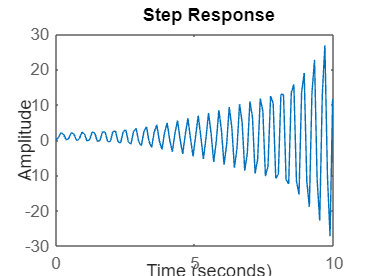

%wzmocnienie 150
k1=150;
mian=[0.01 0.5 3 -10 10];
licz=[1 1];
G=tf(licz,mian);
Gcl1 = minreal(k1*G/(1+k1*G));
%G=G/1+G;
step(Gcl1)
xlim([0 10])
%ylim([-2 3])
saveas(gcf,'k_150.png')